# Lab 7: Coupled Tanks System

% coefficients
g = 981; % cm/s^2
d = 4.45; % cm
do = 0.48; % cm

A1 = (pi * d^2) / 4; % calculate A1
A2 = (pi * d^2) / 4; % calculate A2
Ao1 = (pi * do^2) / 4; % calculate Ao1
Ao2 = (pi * do^2) / 4; % calculate Ao2
c1 = Ao1 * sqrt(2 * g); % calculate c1
c2 = Ao2 * sqrt(2 * g); % calculate c2

Qi = 20; % cm^3/s

% run simulation
out = sim('Tanks.slx', 120);

% calculate steady states (operating point)
h1o = mean(out.h1.Data(end-10:end)) % cm

h1o = 6.2260

h2o = mean(out.h2.Data(end-10:end)) % cm

h2o = 6.2253

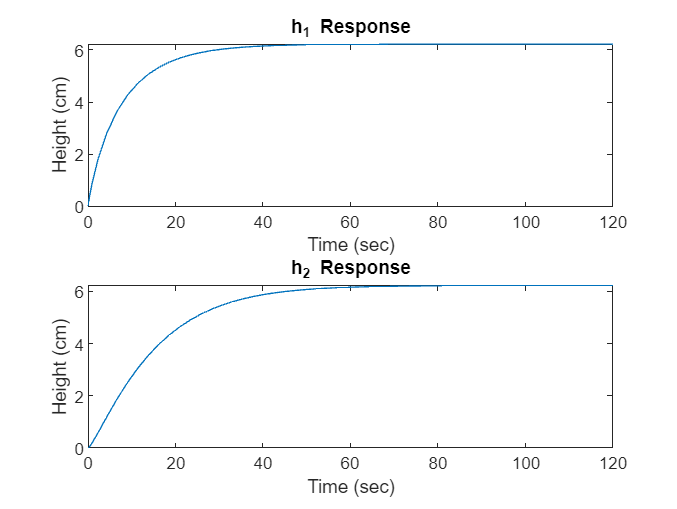

% plot height responses
clf
subplot(2,1,1)
plot(out.h1.Time, out.h1.Data)
title("h_1 Response")
xlabel("Time (sec)")
ylabel("Height (cm)")

subplot(2,1,2)
plot(out.h2.Time, out.h2.Data)
title("h_2 Response")
xlabel("Time (sec)")
ylabel("Height (cm)")

% run simulation at operating point
out = sim('Tanks_OP.slx', 120);

h1 = out.h1.Data - out.h1.Data(1);
h2 = out.h2.Data - out.h2.Data(1);

h1_Fv = mean(h1(end-10:end)) % cm

h1_Fv = 2.0079

h2_Fv = mean(h2(end-10:end)) % cm

h2_Fv = 2.0082


h1_Ts_i = out.h1.Time(h1 >= h1_Fv*0.98);
h1_Ts = h1_Ts_i(1)

h1_Ts = 42.9600


h2_Ts_i = out.h2.Time(h2 >= h2_Fv*0.98);
h2_Ts = h2_Ts_i(1)

h2_Ts = 63.8400


delta_h1 = h1(end) - h1(1)

delta_h1 = 2.0080

delta_h2 = h2(end) - h2(1)

delta_h2 = 2.0083

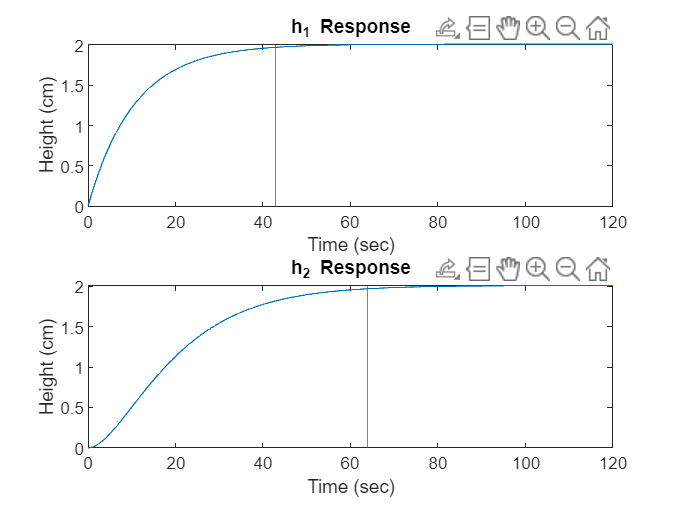

% plot height responses
clf
subplot(2,1,1)
plot(out.h1.Time, h1)
hold on
xline(h1_Ts, 'r')
title("h_1 Response")
xlabel("Time (sec)")
ylabel("Height (cm)")

subplot(2,1,2)
plot(out.h2.Time, h2)
xline(h2_Ts, 'r')
title("h_2 Response")
xlabel("Time (sec)")
ylabel("Height (cm)")

s = zpk("s");
TF1 = 1 / (A1*s + (c1/(2*sqrt(h1o))))

TF1 =
 
   0.064297
  ----------
  (s+0.1033)
 
Continuous-time zero/pole/gain model.
Model Properties


TF2 = (c1/(2*sqrt(h1o))) * (1/(A1*s+(c1/(2*sqrt(h1o))))) * (1/(A2*s+(c2/(2*sqrt(h2o)))))

TF2 =
 
         0.00664
  ---------------------
  (s+0.1033) (s+0.1033)
 
Continuous-time zero/pole/gain model.
Model Properties



%step(3*TF1)
stepinfo(3*TF1)

ans = struct with fields:
         RiseTime: 21.2743
    TransientTime: 37.8818
     SettlingTime: 37.8818
      SettlingMin: 1.6894
      SettlingMax: 1.8666
        Overshoot: 0
       Undershoot: 0
             Peak: 1.8666
         PeakTime: 70.9033


stepinfo(3*TF2)

ans = struct with fields:
         RiseTime: 32.5188
    TransientTime: 56.4918
     SettlingTime: 56.4918
      SettlingMin: 1.6846
      SettlingMax: 1.8675
        Overshoot: 0
       Undershoot: 0
             Peak: 1.8675
         PeakTime: 115.4966


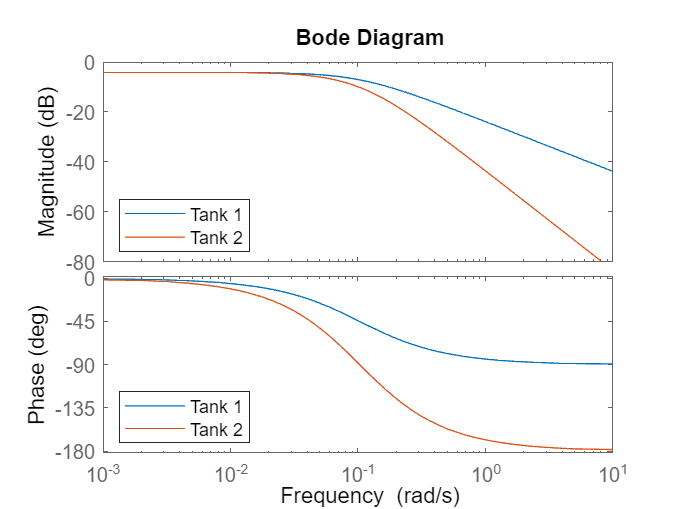

clf
bode(TF1,TF2)
ax = findall(gcf,'type','axes');
legend(ax(3),'Tank 1','Tank 2', 'Location', 'southwest')   
legend(ax(2),'Tank 1','Tank 2', 'Location', 'southwest')  

bandwidth1 = bandwidth(TF1, -6)

bandwidth1 = 0.1783

bandwidth2 = bandwidth(TF2, -6)

bandwidth2 = 0.1030

dqi = 3; % cm^3/s
w_vals = [0.01, 0.1, 0.2, 1]; % rad/s

% Use a for loop to cycle through the w_vals array
for i = 1:length(w_vals)
    % Select the ith value of w array
    w = w_vals(i);

    % Run simulation with current m, store data in a cell array
    study{i} = sim('Tanks_Sin.slx', 120);
end

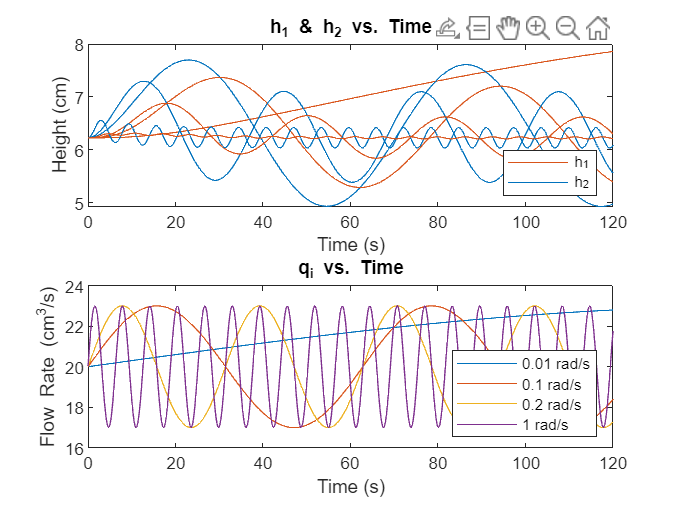

% Use a for loop to cycle through the w_vals array
clf
for i = 1:length(w_vals)
    t = study{i}.tout; % time
    h1 = study{i}.h1.Data; % h1 height
    h2 = study{i}.h2.Data; % h2 height
    qi = study{i}.qi.Data; % qi input
    
    % Graph Height vs. Time 
    hold on
    subplot(2, 1, 1)
    plot(t, h1, 'color', [0 0.4470 0.7410])
    plot(t, h2, 'color', [0.8500 0.3250 0.0980])
    title("h_1 & h_2 vs. Time")
    xlabel("Time (s)")
    ylabel("Height (cm)")
    hold off
    
    % Graph Speed vs. Time 
    hold on
    subplot(2, 1, 2)
    plot(t, qi)
    title("q_i vs. Time")
    xlabel("Time (s)")
    ylabel("Flow Rate (cm^3/s)")
    hold off
end

hold on 
subplot(2, 1, 1)
legend('h_1', 'h_2', 'location', 'southeast')
hold off

hold on
subplot(2, 1, 2)    
legend(string(w_vals) + " rad/s", Location="southeast")
hold off

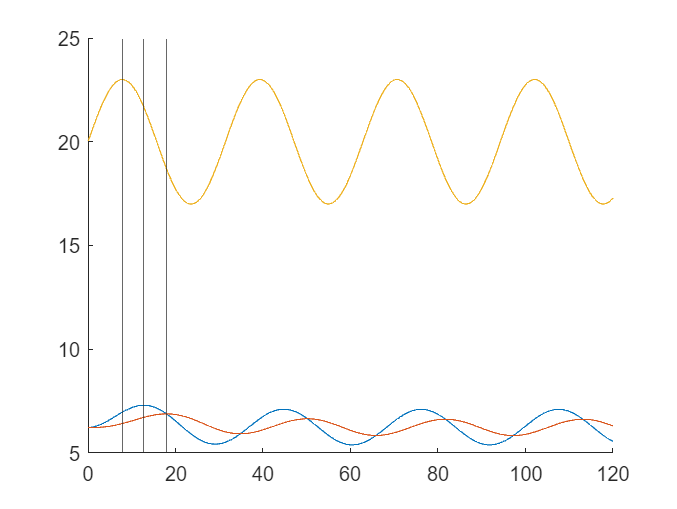

% calculate simulated gain and phase 
i=3; % change this number for each w value
t = study{i}.tout; % time
h1 = study{i}.h1.Data; % h1 height
h2 = study{i}.h2.Data; % h2 height
qi = study{i}.qi.Data; % qi input

peakInd = 1;
[pks1, locs1] = findpeaks(h1);
[pks2, locs2] = findpeaks(h2);
[pksq, locsq] = findpeaks(qi);

clf
hold on
plot(t, h1)
xline(t(locs1(peakInd)))
plot(t, h2)
xline(t(locs2(peakInd)))
plot(t, qi)
xline(t(locsq(peakInd)))

hold off

% refine locs variables to exclude first peaks!
G1 = peak2peak(h1(locs1(peakInd:end):end))/6

G1 = 0.3187

G1db = 20*log10(G1)

G1db = -9.9316

G2 = peak2peak(h2(locs2(peakInd:end):end))/6

G2 = 0.1743

G2db = 20*log10(G2)

G2db = -15.1755


dT1 = t(locsq(peakInd))-t(locs1(peakInd)); % s
dT2 = t(locsq(peakInd))-t(locs2(peakInd)); % s
phi_1 = dT1*w_vals(i)*180/pi % deg

phi_1 = -55.0039

phi_2 = dT2*w_vals(i)*180/pi % deg

phi_2 = -115.5083

[mag1, phase1, wout1] = bode(TF1, w_vals);
[mag2, phase2, wout2] = bode(TF2, w_vals);

% mag1
% mag2
% phase1
% phase2

Step Input $\omega =0$ rad/s

load Lab7_step.mat

t = time(21:end) - time(21);
h1 = heights(21:end,1) - heights(21,1);
h2 = heights(21:end,2) - heights(21,2);

h1_Fv = mean(h1(end-100:end)) % cm

h1_Fv = 4.5538

h2_Fv = mean(h2(end-100:end-60)) % cm

h2_Fv = 4.2667


h1_Ts_i = time(h1 >= h1_Fv*0.98);
h1_Ts = h1_Ts_i(1)

h1_Ts = 73.6481


h2_Ts_i = time(h2 >= h2_Fv*0.98);
h2_Ts = h2_Ts_i(1)

h2_Ts = 99.7001


delta_h1 = h1(end) - h1(1)

delta_h1 = 4.6982

delta_h2 = h2(end) - h2(1)

delta_h2 = 4.4427


flow = median(flow_cms);

% ?????
h1_gain = h1_Fv/flow

h1_gain = 0.1785

h2_gain = h2_Fv/flow

h2_gain = 0.1673

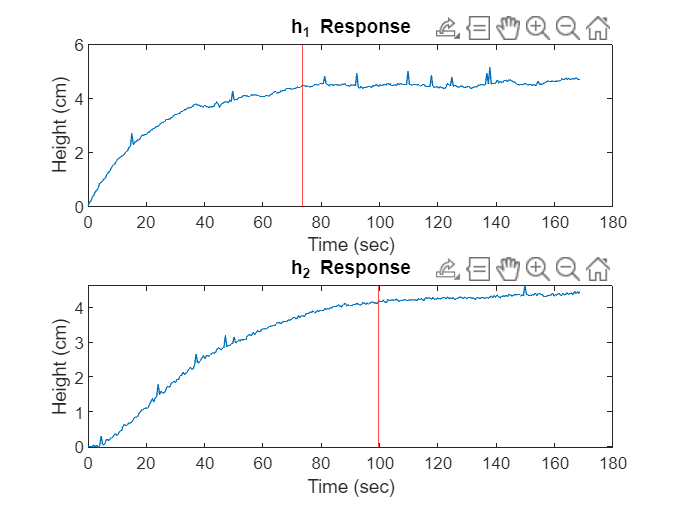

% plot height responses
clf
subplot(2,1,1)
plot(t, h1)
xline(h1_Ts, 'r')
title("h_1 Response")
xlabel("Time (sec)")
ylabel("Height (cm)")

subplot(2,1,2)
plot(t, h2)
xline(h2_Ts, 'r')
title("h_2 Response")
xlabel("Time (sec)")
ylabel("Height (cm)")

Frequency Input $\omega =0\ldotp 1$rad/s

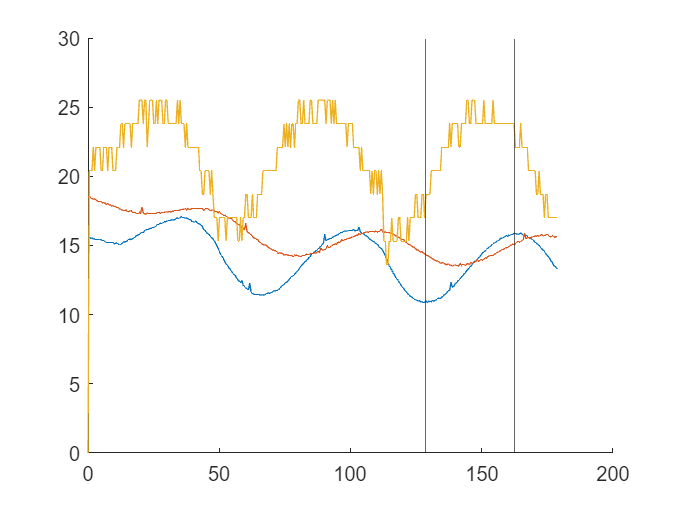

load Lab7_per63.mat

t = time;
h1 = heights(:,1);
h2 = heights(:,2);
qi = flow_cms;

[pks1, locs1] = findpeaks(h1);
[pks2, locs2] = findpeaks(h2);
[pksq, locsq] = findpeaks(qi);

clf
hold on
plot(t, h1)
xline(t(locs1(end-2)))
xline(t(locs1(end-8)))
plot(t, h2)
plot(t, qi)
hold off


G1 = (h1(locs1(end-2)) - h1(locs1(end-8))) / (qi(locs1(end-2)) - qi(236)) 

G1 = 0.5777

G1db = 20*log10(G1)

G1db = -4.7665

dT1 = t(236)-t(locs1(end-8)); % s
phi_1 = dT1*0.1*180/pi % deg

phi_1 = -63.1514


G2 = (h2(locs2(end-3)) - h2(locs2(end-19))) / (qi(locs1(end-2)) - qi(236)) 

G2 = 0.2558

G2db = 20*log10(G2)

G2db = -11.8411

dT2 = t(236)-t(locs2(end-19)); % s
phi_2 = dT2*0.1*180/pi % deg

phi_2 = -126.3028

Frequency Input $\omega =1$rad/s

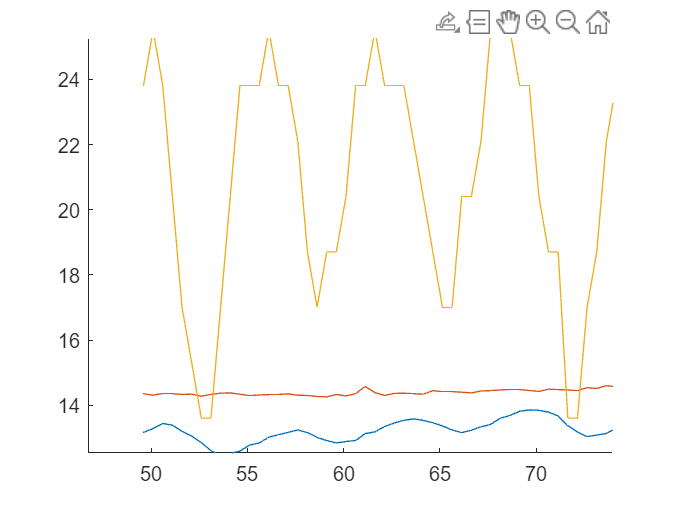

load Lab7_per6.mat

t = time(100:150);
h1 = heights(100:150,1);
h2 = heights(100:150,2);
qi = flow_cms(100:150);

[pks1, locs1] = findpeaks(h1);
[pks2, locs2] = findpeaks(h2);
[pksq, locsq] = findpeaks(qi);

clf
hold on
plot(t, h1)
% xline(t(locs1(end-2)))
% xline(t(locs1(end-8)))0.
plot(t, h2)
plot(t, qi)
hold off


G1 = (h1(locs1(end)) - h1(34)) / (qi(locsq(end)) - qi(33)) 

G1 = 0.0815

G1db = 20*log10(G1)

G1db = -21.7734

dT1 = time(25)-time(28); % s
phi_1 = dT1*1*180/pi % deg

phi_1 = -86.1156


G2 = 0

G2 = 0

G2db = 20*log10(G2)

G2db = -Inf

dT2 = 0; % s
phi_2 = dT2*1*180/pi % deg

phi_2 = 0

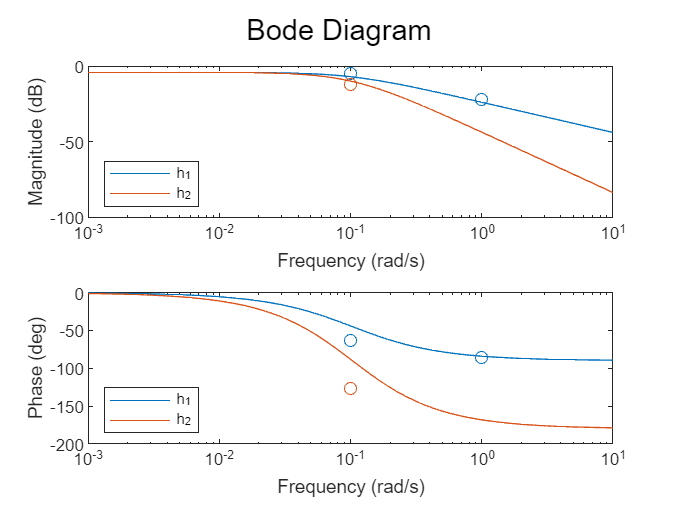

clf
[MAG1,PHASE1,W] = bode(TF1);
[MAG2,PHASE2] = bode(TF2,W);

subplot(2,1,1)
semilogx(W,20*log10(squeeze(MAG1)))
hold on
semilogx(W,20*log10(squeeze(MAG2)))
plot(0.1, -4.7665, 'o', 'color', [0 0.4470 0.7410])
plot(0.1, -11.8411, 'o', 'color', [0.8500 0.3250 0.0980])
plot(1, -21.7734, 'o', 'color', [0 0.4470 0.7410])
hold off
xlabel("Frequency (rad/s)")
ylabel("Magnitude (dB)")
legend('h_1', 'h_2', 'location', 'southwest')
subplot(2,1,2)
semilogx(W,squeeze(PHASE1))
hold on
semilogx(W,squeeze(PHASE2))
plot(0.1, -63.1514, 'o', 'color', [0 0.4470 0.7410])
plot(0.1, -126.3028, 'o', 'color', [0.8500 0.3250 0.0980])
plot(1, -86.1156, 'o', 'color', [0 0.4470 0.7410])
hold off
xlabel("Frequency (rad/s)")
ylabel("Phase (deg)")
legend('h_1', 'h_2', 'location', 'southwest')
sgtitle("Bode Diagram")